syms y(t)
eqn = diff(y ,t) == -12 * y;
cond = y(0) == 1;
dsolve(eqn,cond);
exactSol = @(t)(exp(-12 * t));
% 
% y0(1)
% exactSol(1)
% abs(y0(1) - exactSol(1))

f = @(t,y) -12 * y;
a = 0;
b = 1;
alpha = 1;
N1 = 20;
N2 = 50; 
N3 = 100;
N = [N1, N2, N3];

[y0,t0] = RK2(f, a, b, alpha,N1)

y0 =     1.0000
    0.5800
    0.3364
    0.1951
    0.1132
    0.0656
    0.0381
    0.0221
    0.0128
    0.0074


t0 =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


[y1,t1] = RK2(f, a, b, alpha,N2)

y1 =     1.0000
    0.7888
    0.6222
    0.4908
    0.3871
    0.3054
    0.2409
    0.1900
    0.1499
    0.1182


t1 =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1600
    0.1800


[y2,t2] = RK2(f, a, b, alpha,N3)

y2 =     1.0000
    0.8872
    0.7871
    0.6983
    0.6196
    0.5497
    0.4877
    0.4327
    0.3839
    0.3406


t2 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900



err1 = abs(y0(end) - exactSol(1));
err2 = abs(y1(end) - exactSol(1));
err3 = abs(y2(end) - exactSol(1));
Err = [err1, err2, err3]

Err = 	1.0e+-4 *

    0.1242    0.0091    0.0020


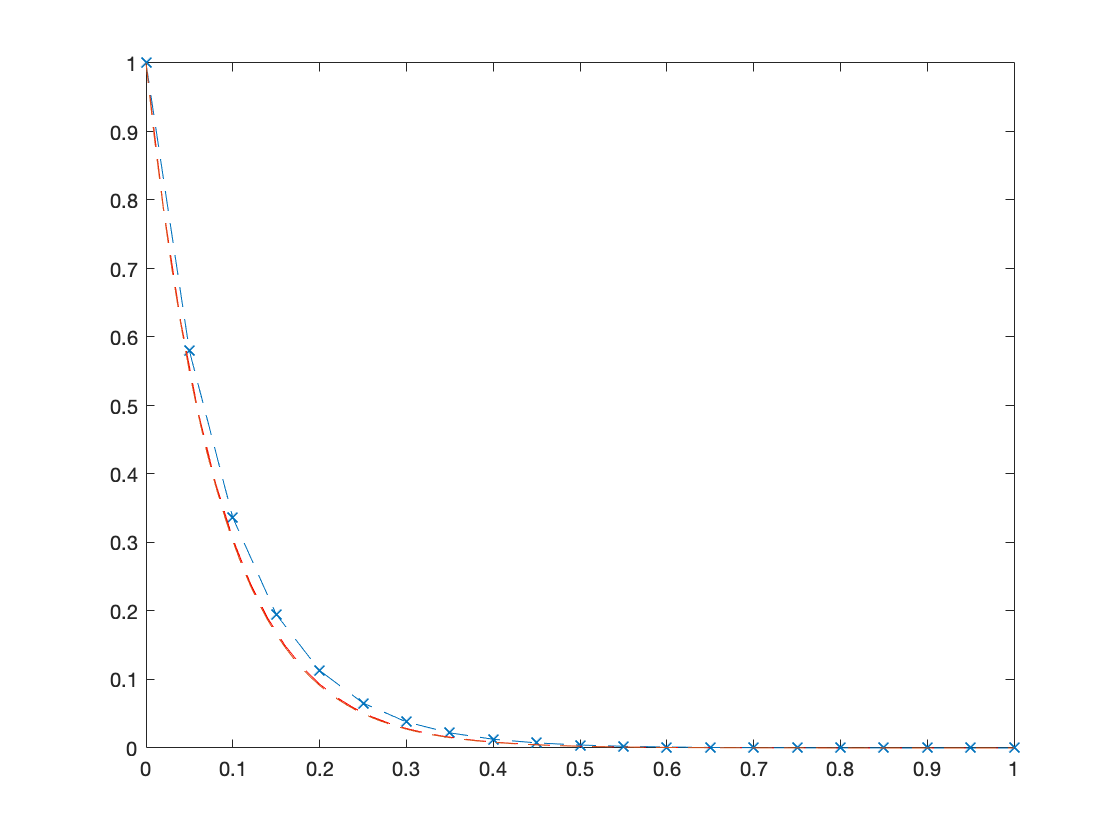


plot(t0, y0, '--x', t1, y1, '--r', t2, y2, '--')

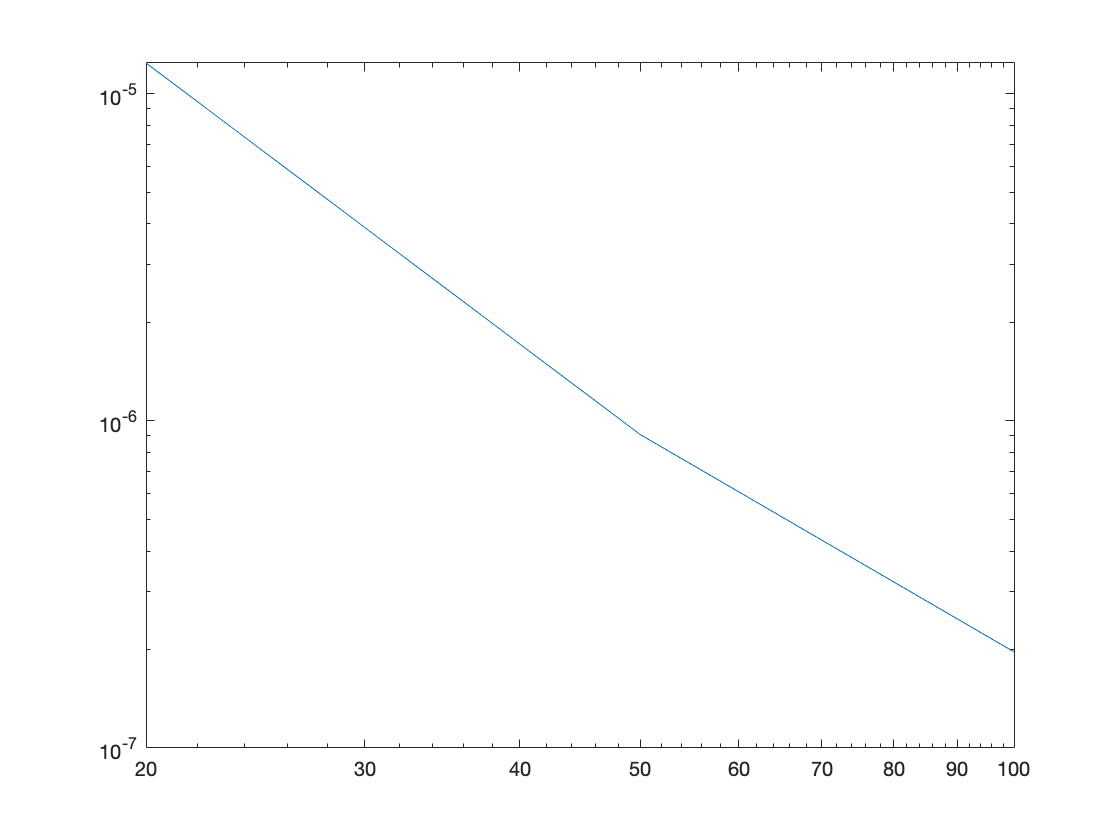

loglog(N, Err)

function [y,t] = RK2(f, a, b, alpha, N)
h = (b - a) / N;
t = zeros(N,1);
y = zeros(N,1);
y(1) = alpha;
t(1) = a;

for i = 1:N
    t(i + 1) = a + i * h;
    %y(i + 1) = y(i) + h * (f(t(i) + (h/2), y(i) + (h / 2) * f(t(i),y(i))));
     y(i+1) = y(i) + (h/2)*(f(t(i),y(i))+f(t(i+1),y(i)+h*f(t(i),y(i))));
end
end
